%
%      @作者：随心390
%      @微信公众号：优化算法交流地
%
tic
clear
clc
%% 输入数据
% x=[38.24,39.57,40.56,36.26,33.48,37.56,38.42,37.52,41.23,41.17,36.08,38.47,38.15,37.51,35.49,39.36,38.09,36.09,40.44,40.33,40.37,37.57];
% y=[20.42,26.15,25.32,23.12,10.54,12.19,13.11,20.44,9.100,13.05,-5.210,15.13,15.35,15.17,14.32,19.56,24.36,23,13.57,14.15,14.23,22.56];
loadatt48();
cityMatrix = load("cities.mat");
cityCoordinates = cityMatrix.cities;
x = cityCoordinates(1, :);
y = cityCoordinates(2, :);
vertexs=[x;y]';
n=length(x);                    %城市数目
h=pdist(vertexs);
dist=squareform(h);             %距离矩阵

第1次迭代：全局最优路线总距离 = 131780.2332
第2次迭代：全局最优路线总距离 = 124767.5642
第3次迭代：全局最优路线总距离 = 114888.4942
第4次迭代：全局最优路线总距离 = 112645.0641
第5次迭代：全局最优路线总距离 = 112645.0641
第6次迭代：全局最优路线总距离 = 112645.0641
第7次迭代：全局最优路线总距离 = 112645.0641
第8次迭代：全局最优路线总距离 = 112645.0641
第9次迭代：全局最优路线总距离 = 112645.0641
第10次迭代：全局最优路线总距离 = 112645.0641
第11次迭代：全局最优路线总距离 = 112645.0641
第12次迭代：全局最优路线总距离 = 112645.0641
第13次迭代：全局最优路线总距离 = 111744.1717
第14次迭代：全局最优路线总距离 = 111744.1717
第15次迭代：全局最优路线总距离 = 111744.1717
第16次迭代：全局最优路线总距离 = 111513.8579
第17次迭代：全局最优路线总距离 = 111513.8579
第18次迭代：全局最优路线总距离 = 108142.3405
第19次迭代：全局最优路线总距离 = 107962.2856
第20次迭代：全局最优路线总距离 = 107962.2856
第21次迭代：全局最优路线总距离 = 107950.6674
第22次迭代：全局最优路线总距离 = 105093.1527
第23次迭代：全局最优路线总距离 = 105093.1527
第24次迭代：全局最优路线总距离 = 104394.5795
第25次迭代：全局最优路线总距离 = 104394.5795
第26次迭代：全局最优路线总距离 = 103261.3555
第27次迭代：全局最优路线总距离 = 103261.3555
第28次迭代：全局最优路线总距离 = 99090.3559
第29次迭代：全局最优路线总距离 = 94386.9182
第30次迭代：全局最优路线总距离 = 92817.1109
第31次迭代：全局最优路线总距离 = 92817.1109
第32次迭代：全局最优路线总距离 = 92817.1109
第33次迭代：全局最优路线总距离 = 927

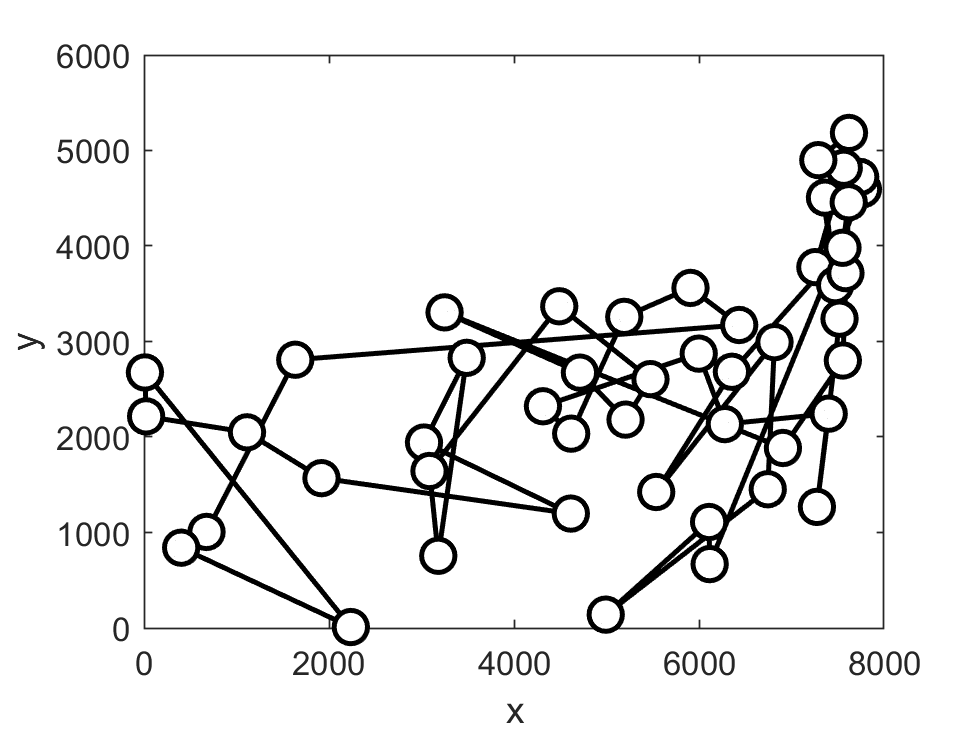


%% 遗传算法参数设置
NIND=50;                        %种群大小
MAXGEN=1000;                    %迭代次数
Pc=0.8;                         %交叉概率
Pm=0.2;                         %变异概率
pSwap=0.2;                      %选择交换结构的概率
pReversion=0.5;                 %选择逆转结构的概率
pInsertion=1-pSwap-pReversion;  %选择插入结构的概率
N=n;                            %染色体长度=城市数目
%% 种群初始化
Chrom=InitPop(NIND,N);
%% 优化
gen=1;                          %计数器
bestChrom=Chrom(1,:);           %初始全局最优个体
bestL=RouteLength(bestChrom,dist);%初始全局最优个体的总距离
BestChrom=zeros(MAXGEN,N);      %记录每次迭代过程中全局最优个体
BestL=zeros(MAXGEN,1);          %记录每次迭代过程中全局最优个体的总距离
while gen<=MAXGEN
    %二元锦标赛选择
    SelCh=BinaryTourment_Select(Chrom,dist);
    %OX交叉
    SelCh=Recombin(SelCh,Pc);
    %变异
    SelCh=Mutate(SelCh,Pm,pSwap,pReversion,pInsertion);
    %将Chrom更新为SelCh
    Chrom=SelCh;
    %计算当前代所有个体总距离
    Obj=ObjFunction(Chrom,dist);
    %找出当前代中最优个体
    [minObj,minIndex]=min(Obj);
    %将当前代中最优个体与全局最优个体进行比较，如果当前代最优个体更好，则将全局最优个体进行替换
    if minObj<=bestL
        bestChrom=Chrom(minIndex,:);
        bestL=minObj;
    end
    %记录每一代全局最优个体，及其总距离
    BestChrom(gen,:)=bestChrom;
    BestL(gen,:)=bestL;
    %显示外层循环每次迭代的信全局最优路线的总距离
    disp(['第' num2str(gen) '次迭代：全局最优路线总距离 = ' num2str(bestL)]);
    %画出每次迭代的全局最优路线图
    figure(1);
    PlotRoute(bestChrom,x,y)
    pause(0.01);
    %计数器加1
    gen=gen+1;
end

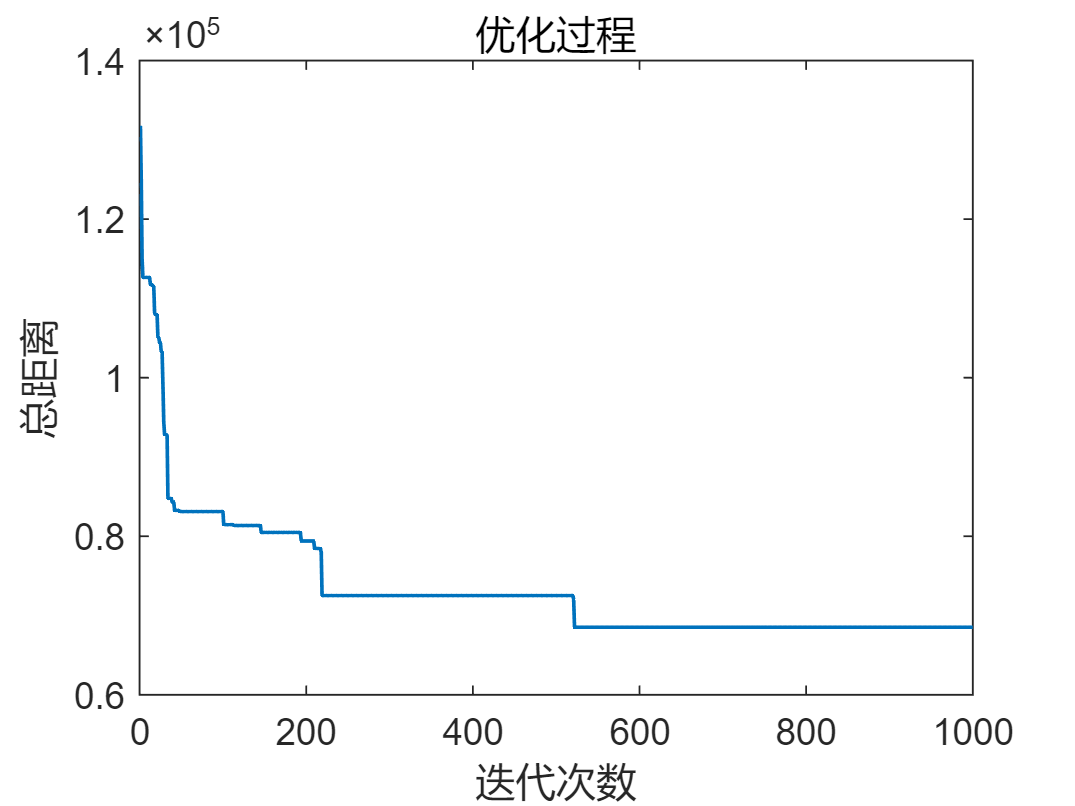

%% 打印每次迭代的全局最优个体的总距离变化趋势图
figure;
plot(BestL,'LineWidth',1);
title('优化过程')
xlabel('迭代次数');
ylabel('总距离');

toc

历时 49.498514 秒。
